## 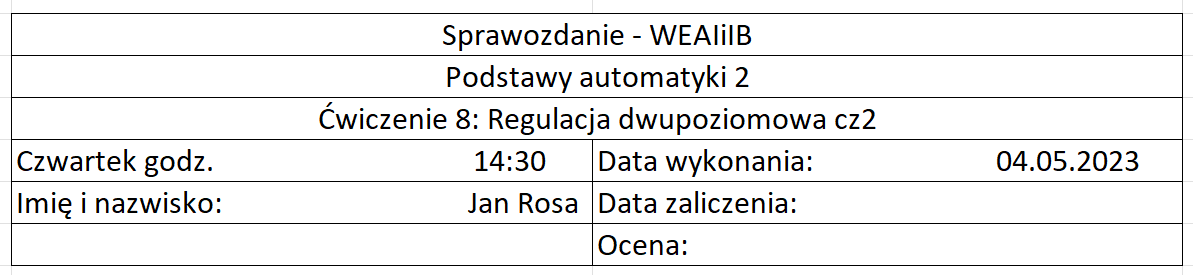

## Wstęp

Celem niniejszego sprawozdania jest zbadanie stabilności układu regulacji z liniowym obiektem i nieliniowym regulatorem statycznym. W zadaniu został przedstawiony zamknięty układ regulacji z liniowym obiektem oraz regulatorem 2-położeniowym bez histerezy i z histerezą. W ramach zadania należy sprawdzić, dla jakiej wartości amplitudy przekaźnika ym oraz histerezy równej h = 0.0, h = 0.05, h = 0.1, amplituda cyklu granicznego będzie większa od 1, 2, 5. W ramach opracowania wyników należy przedstawić rysunek z przebiegiem wielkości regulowanej w układzie oraz narysować wykres Nyquista części liniowej wraz z wykresem krytycznym. Porównanie wyników analitycznych z otrzymanymi podczas laboratorium będzie dodatkową analizą.

Obiekty do analizy:

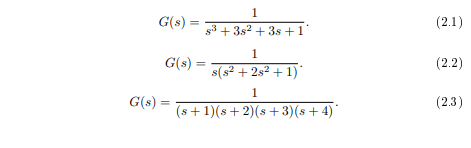

Model w simulinku

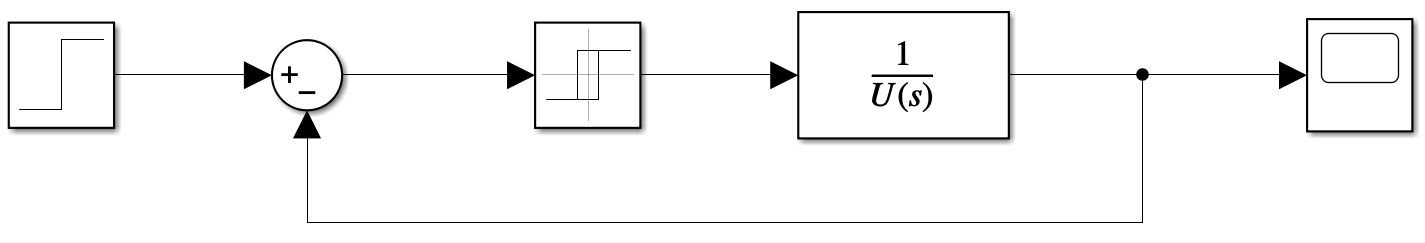

## Przebieg Ćwiczenia

#### Obiekt 1

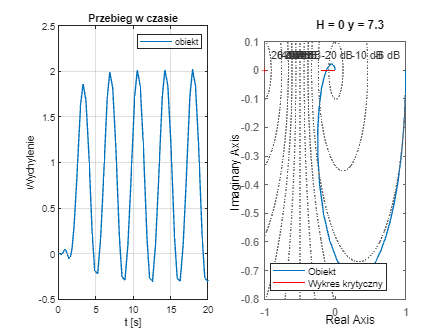

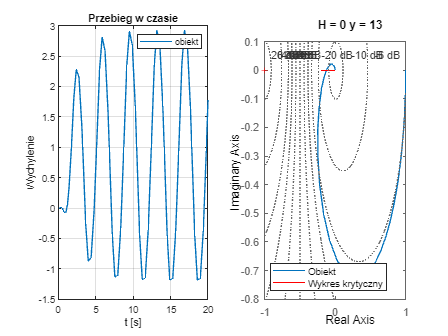

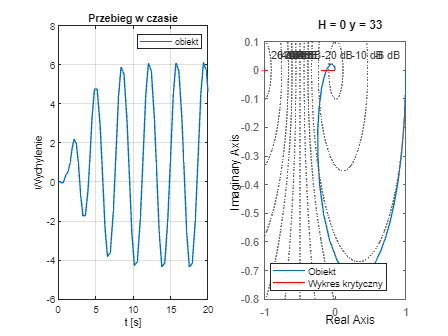

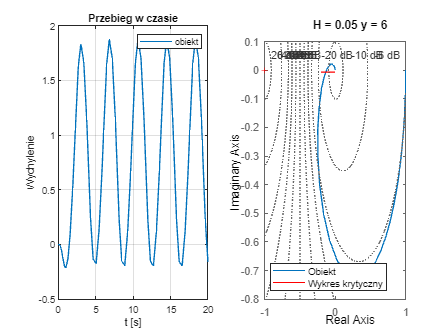

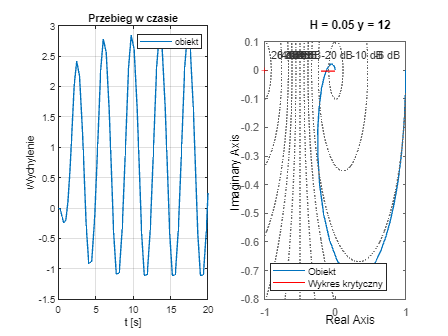

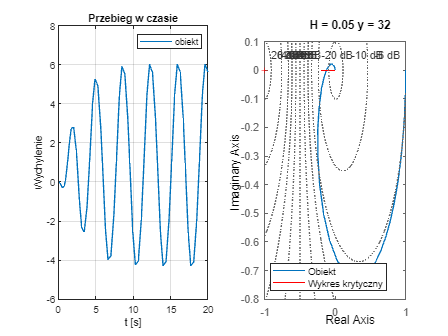

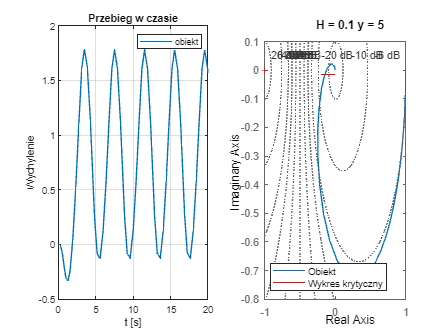

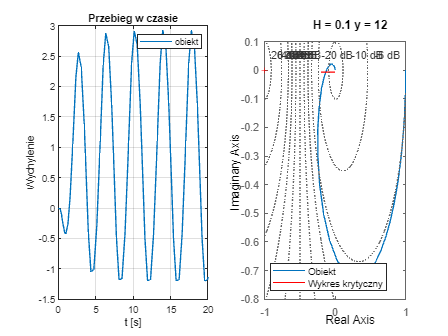

G = [1, 3, 3, 1];
h_vec = [0, 0.05, 0.1];
y_mat = [[  7.3, 13, 33];
         [  6, 12, 32];
         [  5, 12, 31]];

for i = 1:3
    for j = 1:3
        h = h_vec(i);
        y = y_mat(i, j);
        test(G, h, y);
    end
end

#### Obiekt 2

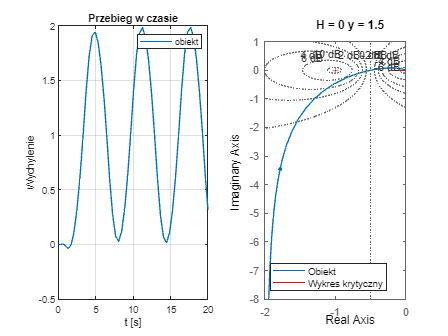

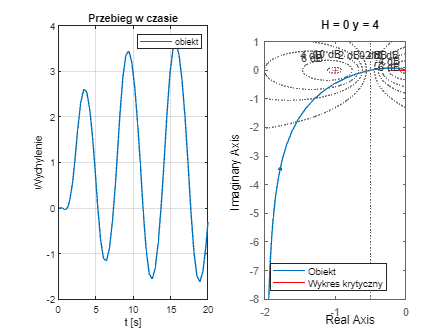

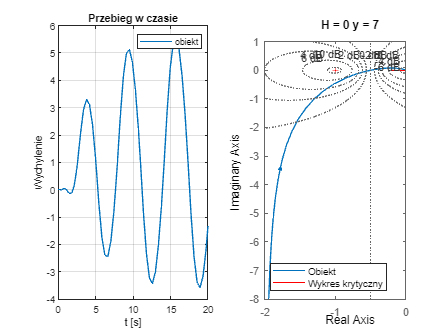

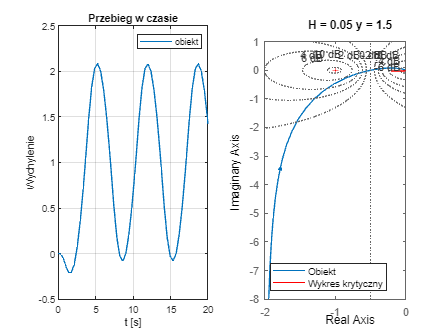

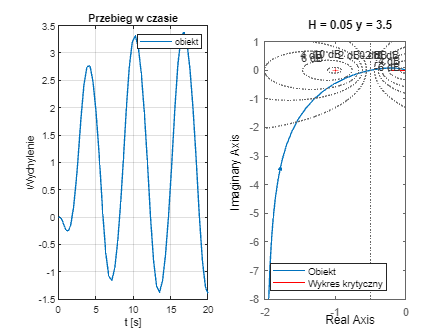

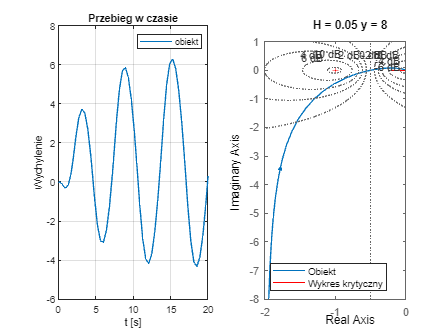

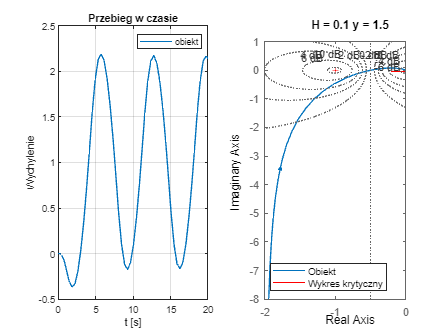

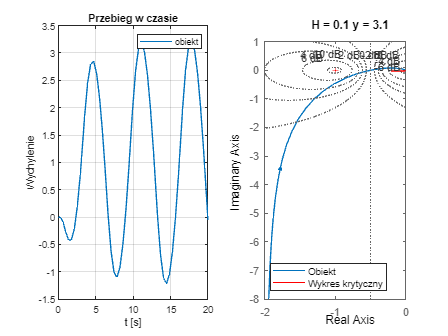

G = [1, 2, 1, 0];
y_mat = [[  1.5, 4, 7];
         [  1.5, 3.5, 8];
         [  1.5, 3.1, 7.3]];
y = 10;
for i = 1:3
    for j = 1:3
        h = h_vec(i);
        y = y_mat(i, j);
        test(G, h, y);
    end
end

#### Obiekt 3

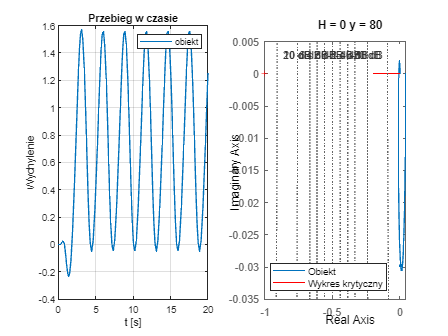

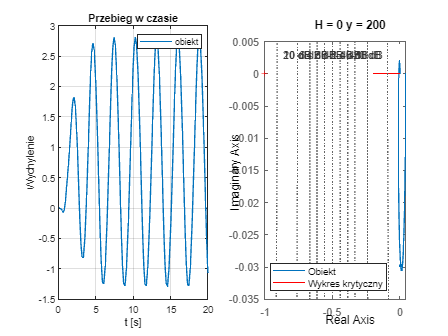

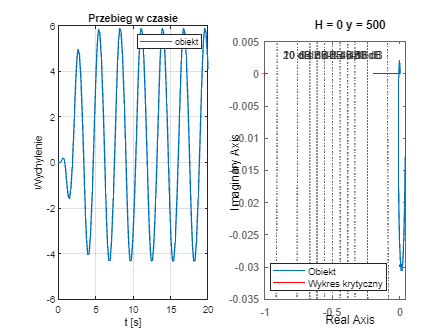

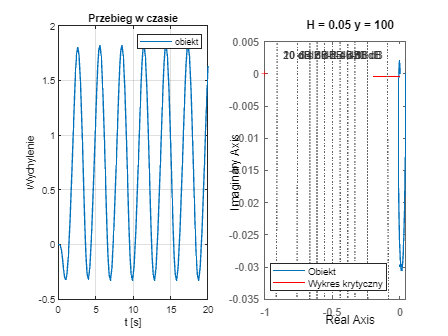

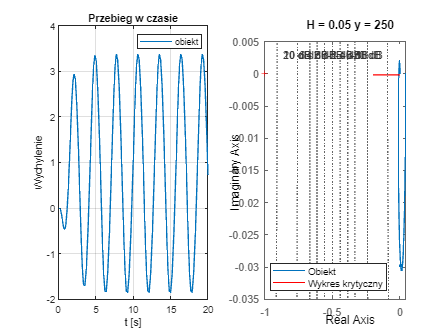

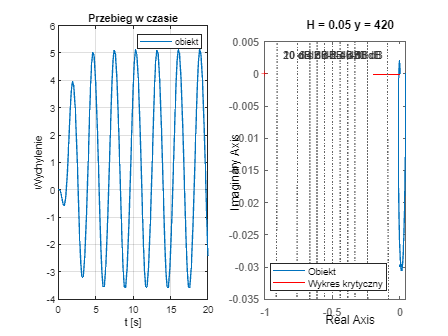

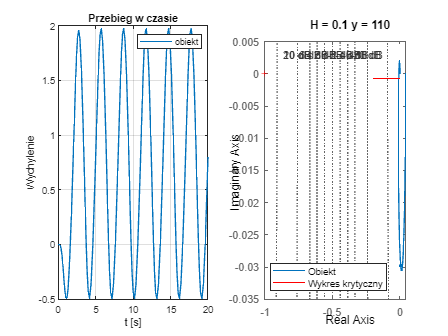

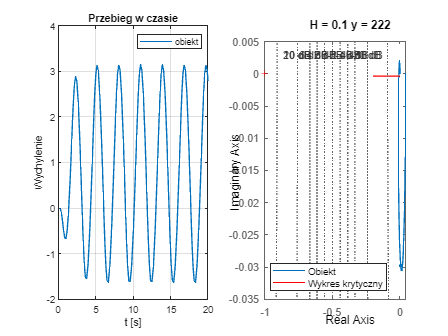

G = [1, 10, 35, 50, 24];
y_mat = [[  80, 200, 500];
         [  100, 250, 420];
         [  110, 222, 450]];
y = 10;
for i = 1:3
    for j = 1:3
        h = h_vec(i);
        y = y_mat(i, j);
        test(G, h, y);
    end
end

function [] = test(G, h, ym)
    obiekt = tf([0,0,0,1], G);
    c = (-pi*h)/(4 * ym);
    out = sim("obiekt_reg.slx");
    figure;
    subplot(1, 2, 1);
    plot(out.ScopeData.time, out.ScopeData.signals.values);
    title("Przebieg w czasie");
    grid on;
    xlabel("t [s]")
    ylabel("Wychylenie")
    legend("obiekt")
    subplot(1, 2, 2);
    n = nyquistplot(obiekt);
    hold on;
    opt = getoptions(n);
    opt.ShowFullContour = 'off';
    setoptions(n, opt);
    zoomcp(n)
    plot([-0.2, 0], [c, c], 'r');
    title("H = " + string(h) + " y = " + string(ym))
    legend(["Obiekt","Wykres krytyczny"], 'Location','southwest')
    grid on;
    hold off;

end

## Wnioski

Z przeprowadzonego ćwiczenia wynika, że układ regulacji z liniowym obiektem i nieliniowym regulatorem statycznym może wykazywać niestabilność, gdyż jego charakterystyka może przeciąć się z krzywą Nyquista poza punktem (-1,0). Wprowadzenie histerezy w regulatorze powoduje, że charakterystyka staje się asymetryczna, co może wpłynąć na stabilność układu regulacji.

W ćwiczeniu został zastosowany model simulinkowy, który umożliwił badanie wpływu parametrów regulatora na stabilność układu regulacji. Dzięki temu, możliwe było określenie wartości amplitudy przekaźnika oraz histerezy, dla których amplituda cyklu granicznego przekracza wartości 1, 2 lub 5.

Wnioskiem z ćwiczenia jest fakt, że dobór parametrów regulatora ma kluczowe znaczenie dla stabilności układu regulacji, a zastosowanie modeli symulacyjnych pozwala na łatwe badanie wpływu tych parametrów na charakterystykę układu.